## Segmenting the Ball

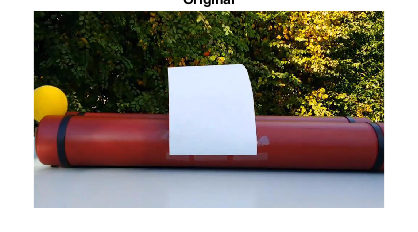

load ball_frames.mat
figure, imshow(videoFrame)
title("Original")

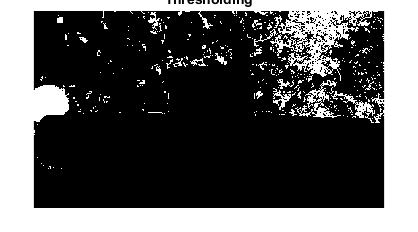


Ihsv = rgb2hsv(videoFrame);
% extract hue plane
hue = Ihsv(:,:,1);
% apply threshold
BW = hue >= 0.1 & hue < 0.15;

figure, imshow(BW)
title('Thresholding')

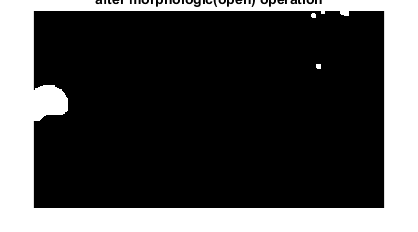

% Use morphological operations to remove disturbances
SE = strel('disk', 7);
BW = imopen(BW,SE);
figure, imshow(BW),
title('after morphologic(open) operation') 

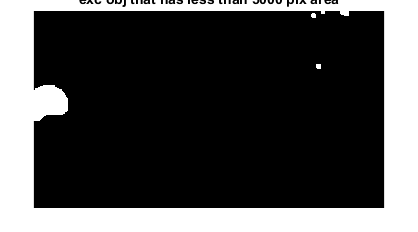

% Exclude any objects which have less than 5000 pixel area.
mask = bwareaopen(BW,5000);
figure, imshow(BW),
title('exc obj that has less than 5000 pix area') 

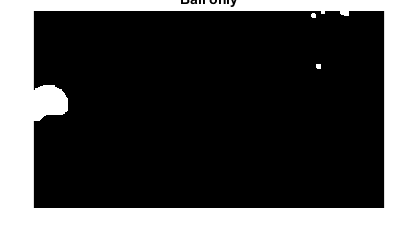


% Exclude the objects that are touching the border.
%mask = imclearborder(BW); 
figure, imshow(BW),
title('Ball only') 

% get shape properties of all object which have more than 5000 pixels.
props = regionprops('table',mask,'Centroid','MajorAxisLength');

### Highlight the detected object

Create a **AlphaBlender** object to highlight the detected object in the original video frame

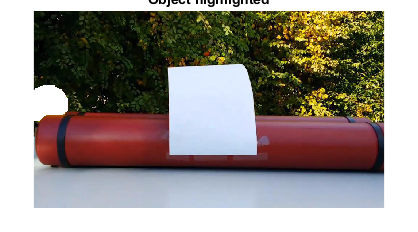

alphaBlending = vision.AlphaBlender;
alphaBlending.Operation = 'Highlight selected pixels';

frame = alphaBlending(videoFrame, mask);
figure, imshow(frame)
title('Object highlighted')

### Insert a text number of detected objects

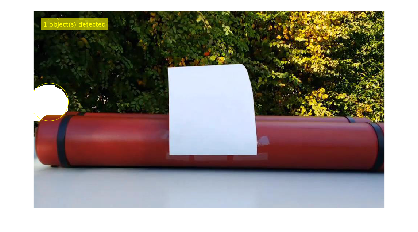

numObj = length(props.MajorAxisLength);

str = [num2str(numObj),' object(s) detected'];

frame = insertText(frame,[20 20], str, 'textColor',[1 1 0],...
    'FontSize',18);

% Draw a circle around the detected objects
frame = insertShape(frame, 'Circle', ...
    [props.Centroid, props.MajorAxisLength/2]) ;
imshow(frame)

imwrite(frame, "results.png")